**1D Electric Potential of Line Charge: **

%xp = linspace(.1,1,100);
y = linspace(0.1,4,100) %distance from the line charge

y =     0.1000    0.1394    0.1788    0.2182    0.2576    0.2970    0.3364    0.3758    0.4152    0.4545    0.4939    0.5333    0.5727    0.6121    0.6515    0.6909    0.7303    0.7697    0.8091    0.8485    0.8879    0.9273    0.9667    1.0061    1.0455    1.0848    1.1242    1.1636    1.2030    1.2424    1.2818    1.3212    1.3606    1.4000    1.4394    1.4788    1.5182    1.5576    1.5970    1.6364    1.6758    1.7152    1.7545    1.7939    1.8333    1.8727    1.9121    1.9515    1.9909    2.0303


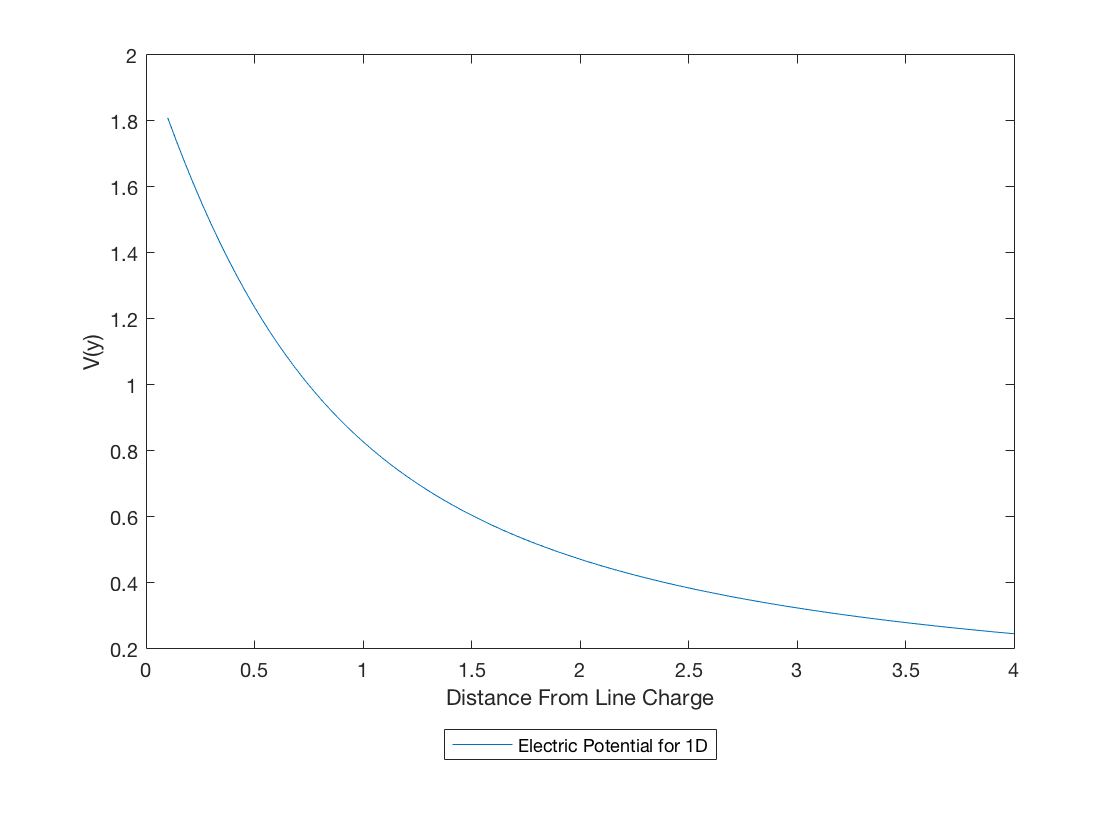

f=@(xp,y) ((2*xp)./sqrt(y.^2+xp.^2)); %In this case the electric potential
%fvector = np.vectorize(f) 
v = zeros(1,100); %empty list 
for i = 1:100
    variable = y(i);
    x =linspace(0,1,100); %setting up the limits
    f=integral (@(xp) ((2*xp)./sqrt(variable.^2+xp.^2)),0,1);
    %v.append(sci.romberg(f,0,1)) 
    v(i) = f;
end
plot (y,v)
legend('Electric Potential for 1D','Location','southoutside')
xlabel('Distance From Line Charge')
ylabel('V(y)')

**1D Electric Field of Line Charge: **

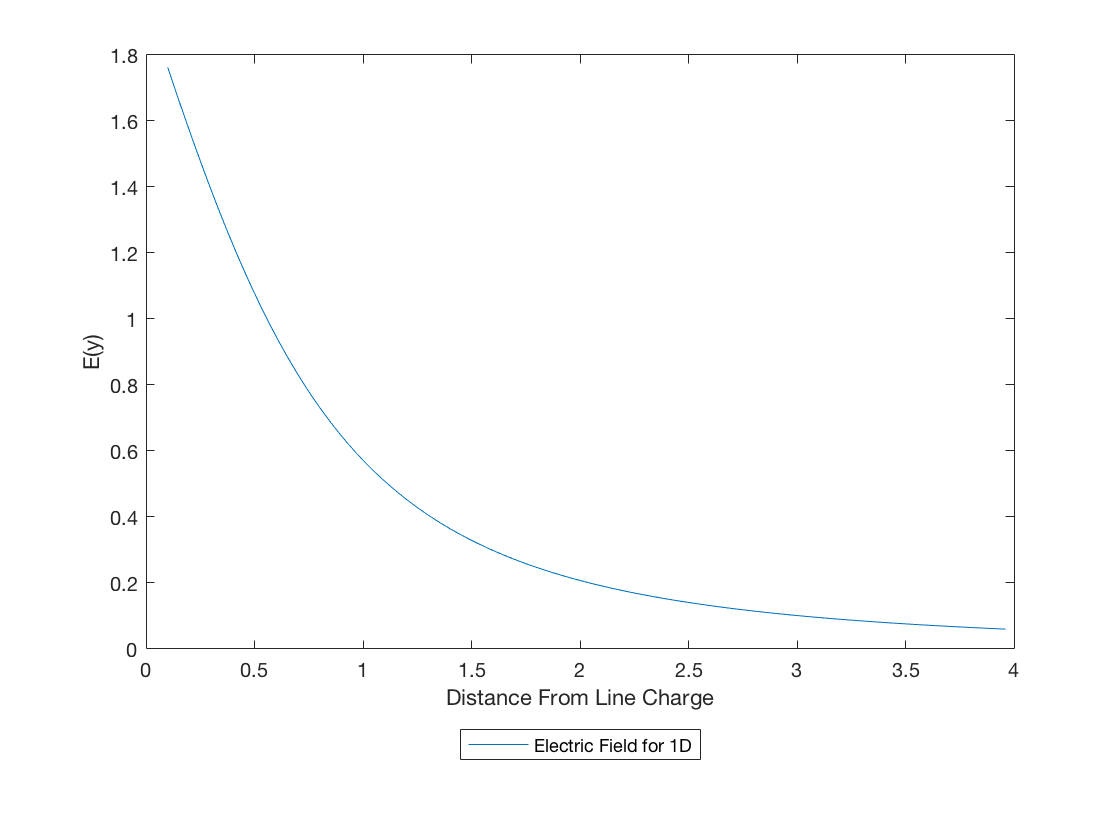

%E1D=(-1)*(diff(v)./diff(y)); %d/dx potenital the first derivative 
[Ey1D, Ex1D] = Der(-1*v,y); 
plot (Ex1D, Ey1D)
legend('Electric Field for 1D','Location','southoutside')
xlabel('Distance From Line Charge')
ylabel('E(y)')

**2D Electric Potential of Line Charge: **